## 耦合项对于位置环的影响

clc

ulogOBJ = ulogreader("HILSimData\stable2\log_0_2021-6-30-08-04-20.ulg");
msg = readTopicMsgs(ulogOBJ);

## 滤波姿态和位置

attitude = msg.TopicMessages{35};
attitude_time = attitude.timestamp;
q = attitude.q;
maxi = size(q,1);

local_position = msg.TopicMessages{43};
local_position_time = local_position.timestamp;
for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_1 = N3(:,3);

clear N3 attitude attitude_time q
%对比数据
ulogOBJ = ulogreader("HILSimData\stable2\log_1_2021-6-30-08-07-22.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{31};
attitude_time = attitude.timestamp;
q = attitude.q;
maxi = size(q,1);
local_position2 = msg.TopicMessages{39};
local_position_time2 = local_position2.timestamp;


for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_2 = N3(:,3);

clc

clear N3 attitude attitude_time q
%对比数据
ulogOBJ = ulogreader("HILSimData\stable2\log_6_2021-6-30-08-11-34.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{31};
attitude_time = attitude.timestamp;
q = attitude.q;
maxi = size(q,1);
local_position3 = msg.TopicMessages{39};
local_position_time3 = local_position3.timestamp;


for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_3 = N3(:,3);

% figure(7)
% plot(h3_1(1:2400))
% hold on
% 
% plot(h3_2(1:2400))
% hold on
% 
% plot(h3_3)

位置k_cp 0.0  0.5 0.4

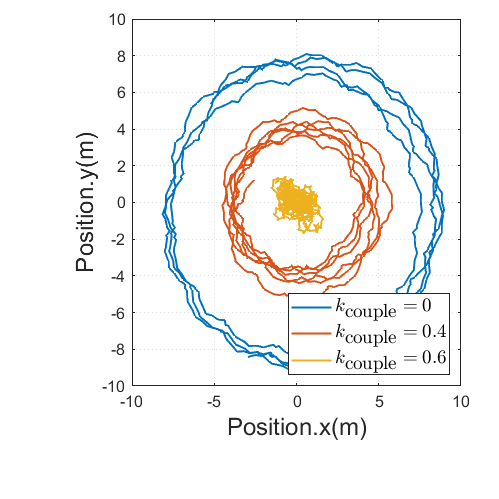

figure(2)
plot(local_position.x(500:1100),local_position.y(500:1100),'LineWidth',1.5)
hold on
plot(local_position3.x(700:1400),local_position3.y(700:1400),"LineWidth",1.5)
hold on 
plot(local_position2.x(300:1100),local_position2.y(300:1100),"LineWidth",1.5)
legend('$k_{\textrm{couple}}=0$','$k_{\textrm{couple}}=0.4$','$k_{\textrm{couple}}=0.6$','Interpreter','latex',"FontSize",14)
xlabel('Position.x(m)',"FontSize",18)
ylabel('Position.y(m)',"FontSize",18)